## Generation of a Lagrange-Euler model for a **P(rismatic)R(evolute)R(evolute) Multi-body System**

### **Free body diagram of the system:**

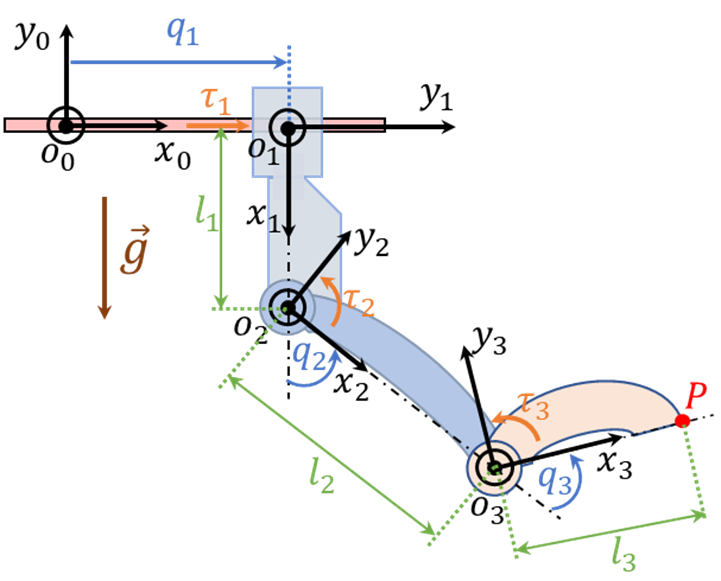

Here, all definitions such as generalized coordinates (q) and generalized forces (tau) are already determined.

### Steps to take

- Create symbolic variables of all parameters, e.g. generalized coordinates

- Create inertial parameters in symbolic form

- Determine orientation kinematics

- Determine translational kinematics

- Determine the coordinates of the Center of Masses (CoM) relative to the fixed frame

- Determine the translational velocities of the CoM's, expressed in the fixed frame

- Computation of the translational kinetic energy

- Computation of the angular velocities of the coordinate frames "glued" to the links relative to the fixed frame

- Computation of the rotational kinetic energy

- Computation of the potential energy due to gravity

- Computation of the potential energy stored in the torsional spring of stiffness c_3 in joint 3

- Computation of the total kinetic & potential energies and determining Lagrangian

- Computation of the Lagrange-Euler Equations of Motion (L-E EoM)

#### 1.

clear all; close all; clc

% Initialize symbolic variables
syms q_1 q_2 q_3
syms qd_1 qd_2 qd_3
syms qdd_1 qdd_2 qdd_3
syms m_1 m_2 m_3
syms I_xx_1 I_yy_1 I_zz_1 I_xx_2 I_yy_2 I_zz_2 I_xx_3 I_yy_3 I_zz_3
syms l_1 l_2 l_3 g
syms alf_1 bet_1 alf_2 bet_2 alf_3 bet_3
syms c_3
syms fc_1 fc_2 fc_3 fv_1 fv_2 fv_3
Pi = sym(pi);     % symbolic variable for number pi (3.14159...)

% Generating symbolic vectors of generalized coordinates (q), speeds (qd) and
% accelerations (qdd)
q = [q_1; q_2; q_3];                           % generalized coordinates (joint motions)
qd = [qd_1; qd_2; qd_3];                       % joint speeds
qdd = [qdd_1; qdd_2; qdd_3];                   % joint accelerations

#### 2. Create Inertial Parameters in symbolic form

m = [m_1; m_2; m_3];                           % masses of the links

% inertia tensor of link 1 determined wrt. the coordinate frame at the center of mass of this link
I_k{1} = [I_xx_1       0       0
               0  I_yy_1       0
               0       0  I_zz_1];             

% inertia tensor of link 2 determined wrt. the coordinate frame at the center of mass of this link
I_k{2} = [I_xx_2       0       0
               0  I_yy_2       0
               0       0  I_zz_2];             

% inertia tensor of link 3 determined wrt. the coordinate frame at the center of mass of this link
I_k{3} = [I_xx_3       0       0
               0  I_yy_3       0
               0       0  I_zz_3];             

% Coordinates of Center of Masses (CoM's)
p_c_k{1} = [alf_1; bet_1; 0];                  % coordinates of the center of mass of link 1 expressed relative to the coordinate frame o1_x1_y1_z1 "glued" to this link                          
p_c_k{2} = [alf_2; bet_2; 0];                  % coordinates of the center of mass of link 2 expressed relative to the coordinate frame o2_x2_y2_z2 "glued" to this link                          
p_c_k{3} = [alf_3; bet_3; 0];                  % coordinates of the center of mass of link 3 expressed relative to the coordinate frame o3_x3_y3_z3 "glued" to this link

#### 3. Orientation kinematics

% orientation of o1_x1_y1_z1 relative to the fixed frame o0_x0_y0_z0
R_0{1} = Rz_theta(-0.5*Pi,3);                 

% orientation of o2_x2_y2_z2 relative to o1_x1_y1_z1
R_2_1 = Rz_theta(q_2,3);                      

% orientation of o3_x3_y3_z3 relative to o2_x2_y2_z2
R_3_2 = Rz_theta(q_3,3);                      

% orientation of o2_x2_y2_z2 relative to the fixed frame o0_x0_y0_z0
R_0{2} = simplify(R_0{1} * R_2_1);

% orientation of o3_x3_y3_z3 relative to the fixed frame o0_x0_y0_z0 (forward orientation kinematics)
R_0{3} = simplify(R_0{2} * R_3_2);

#### 4. Translational kinematics

o_0{1} = [q_1; 0; 0];                          % coordinates of the origin of o1_x1_y1_z1 expressed in the fixed frame o0_x0_y0_z0
o_0{2} = o_0{1} + R_0{1}*[l_1; 0; 0];          % coordinates of the origin of o2_x2_y2_z2 expressed in the fixed frame o0_x0_y0_z0
o_0{3} = o_0{2} + R_0{2}*[l_2; 0; 0];          % coordinates of the origin of o3_x3_y3_z3 expressed in the fixed frame o0_x0_y0_z0

P_0  = o_0{3} + R_0{3}*[l_3; 0; 0];            % coordinates of the end-point expressed in the fixed frame o0_x0_y0_z0 (forward translational kinematics)

#### 5. Expressing the coordinates of the center of masses of the links into the fixed frame $o_{0}x_{0}y_{0}z_{0}$

for k = 1 : 3,
    p_c_0{k} = o_0{k} + R_0{k}*p_c_k{k};        % coordinates of the center of mass of link k expressed in o0_x0_y0_z0
end

#### 6. Computation of translational velocities of the center of masses of the links expressed in the fixed frame $o_{0}x_{0}y_{0}z_{0}$

for k = 1 : 3,
    pd_c_0{k} = jacobian(p_c_0{k},q) * qd;      % chain rule for computation of time-derivative: 'jacobian' computes partial derivatives of xyz-coordinates of the center of mass 
                                                % wrt. the joint coordinates, which is followed by multiplication with the vector of joint speeds
end

#### 7. Computation of the translational kinetic energy

K_t = 0;
for k = 1 : 3,
    K_t = K_t + simplify(0.5*m(k)*transpose(pd_c_0{k})*pd_c_0{k});  % it is recommended to use 'simplify' to come up with the most compact symbolic expressions
end
K_t = simplify(K_t)

$$K\_t = \begin{array}{l} \frac{m_{3}\,{\left({\mathrm{qd}}_{3}\,\left(\sigma_{3}+\sigma_{2}\right)+{\mathrm{qd}}_{2}\,\left(\sigma_{3}+\sigma_{2}+l_{2}\,\sin\left(q_{2}\right)\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\,\left({\mathrm{alf}}_{2}\,\cos\left(q_{2}\right)-{\mathrm{bet}}_{2}\,\sin\left(q_{2}\right)\right)\right)}^{2}}{2}+\frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,{\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{3}\,\left(\sigma_{4}-\sigma_{1}\right)+{\mathrm{qd}}_{2}\,\left(\sigma_{4}-\sigma_{1}+l_{2}\,\cos\left(q_{2}\right)\right)\right)}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{2}}^{2}\,{\left({\mathrm{bet}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{alf}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{bet}}_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{2}={\mathrm{alf}}_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{3}={\mathrm{bet}}_{3}\,\cos\left(q_{2}+q_{3}\right)\\ \sigma_{4}={\mathrm{alf}}_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

#### 8. Computation of the angular velocities of the coordinate frames "glued" to the links relative to the fixed frame $o_{0}x_{0}y_{0}z_{0}$ and expressed in $o_{0}x_{0}y_{0}z_{0}$

for k = 1 : 3,
    Rd_0{k} = diff(R_0{k},q_1)*qd_1 + diff(R_0{k},q_2)*qd_2 + diff(R_0{k},q_3)*qd_3;  % chain rule for time-derivative: compute a sum of products
                                                                                      % between partial derivatives of the rotation matrix R_0{k} 
                                                                                      % wrt. each joint coordinates and the corresponding joint speed
% below is a more elegant way to program the chain rule for time-derivative of R_0{k}                                                                                       
%     Rd_0{k} = zeros(3);                               % initialize 3x3 matrix containing zeros only
%     for n = 1 : 3,
%         Rd_0{k} = Rd_0{k} + diff(R_0{k},q(n))*qd(n);  
%     end
    
    S_w_0{k} = simplify(Rd_0{k} * transpose(R_0{k}));                                 % calculation of skew-symmetric matrix containing xyz-elements of the angular velocity vector
    w_0{k} = [S_w_0{k}(3,2); S_w_0{k}(1,3); S_w_0{k}(2,1)];                           % create vector of angular velocities by extracting its xyz-elements from the skew-symmetric matrix 
end

#### 9. Computation of the rotational kinetic energy

K_r = 0;
for k = 1 : 3,
    K_r = K_r + simplify(0.5*transpose(w_0{k})*R_0{k}*I_k{k}*transpose(R_0{k})*w_0{k});  % it is recommended to use 'simplify' to come up with the most compact symbolic expressions
end
K_r = simplify(K_r)

$$K\_r = \frac{I_{\mathrm{zz},2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+I_{\mathrm{zz},3}\,\left(\frac{{\mathrm{qd}}_{2}}{2}+\frac{{\mathrm{qd}}_{3}}{2}\right)\,\left({\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}\right)$$

#### 10. Computation of the potential energy due to gravity

P_g = 0;
for k = 1 : 3,
    P_g = P_g + m(k)*g*p_c_0{k}(2);     % since the gravity force acts in the negative direction of the y-axis of the fixed coordinate frame o0_x0_y0_z0, 
                                        % we use y-coordinates of the center of mass of each link (2nd element of p_c_0{k}) expressed in o0_x0_y0_z0
end

#### 11. Computation of the potential energy stored in the torsional spring of stiffness $c_{3}$ in joint 3

P_e = 0.5*c_3*q_3^2 

$$P\_e = \frac{c_{3}\,{q_{3}}^{2}}{2}$$

#### 12. Computation of the total kinetic and potential energies, as well as of Lagrangian

K = K_t + K_r;                          % total kinetic energy
P = P_g + P_e;                          % total potential energy
Lagr = simplify(K - P)                  % Lagrangian

$$Lagr = \begin{array}{l} \frac{m_{3}\,{\left({\mathrm{qd}}_{3}\,\left(\sigma_{4}+\sigma_{3}\right)+{\mathrm{qd}}_{2}\,\left(\sigma_{4}+\sigma_{3}+l_{2}\,\sin\left(q_{2}\right)\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\,\left({\mathrm{alf}}_{2}\,\cos\left(q_{2}\right)-{\mathrm{bet}}_{2}\,\sin\left(q_{2}\right)\right)\right)}^{2}}{2}+\frac{I_{\mathrm{zz},2}\,{{\mathrm{qd}}_{2}}^{2}}{2}-\frac{c_{3}\,{q_{3}}^{2}}{2}+\frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,{\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{3}\,\left(\sigma_{2}-\sigma_{1}\right)+{\mathrm{qd}}_{2}\,\left(\sigma_{2}-\sigma_{1}+l_{2}\,\cos\left(q_{2}\right)\right)\right)}^{2}}{2}+g\,m_{2}\,\left(l_{1}+{\mathrm{alf}}_{2}\,\cos\left(q_{2}\right)-{\mathrm{bet}}_{2}\,\sin\left(q_{2}\right)\right)+g\,m_{3}\,\left(l_{1}+\sigma_{2}-\sigma_{1}+l_{2}\,\cos\left(q_{2}\right)\right)+{\mathrm{alf}}_{1}\,g\,m_{1}+\frac{m_{2}\,{{\mathrm{qd}}_{2}}^{2}\,{\left({\mathrm{bet}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{alf}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}}{2}+I_{\mathrm{zz},3}\,\left(\frac{{\mathrm{qd}}_{2}}{2}+\frac{{\mathrm{qd}}_{3}}{2}\right)\,\left({\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{bet}}_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{2}={\mathrm{alf}}_{3}\,\cos\left(q_{2}+q_{3}\right)\\ \sigma_{3}={\mathrm{alf}}_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{4}={\mathrm{bet}}_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

#### 13. Computation of Lagrange-Euler equations of motion

Tau = sym(zeros(3,1));   % create 3x1 vector of Lagrange-Euler equations (initialize with zeros)
for k = 1 : 3,
    DLagr_Dqd{k} = simplify(diff(Lagr,qd(k)));            % partial derivative of Lagrangian wrt. the speed of joint k
    d_DLagr_Dqd_dt{k} = 0;
    for n = 1 : 3,
        % chain rule for time-derivative of DLagr_Dqd{k}:
        % sum of products between partial derivatives of DLagr_Dqd{k} wrt. each joint position (generalized coordinate) and the corresponding joint speed, 
        % as well of products between partial derivatives of DLagr_Dqd{k} wrt. each joint speed and the corresponding joint acceleration
        d_DLagr_Dqd_dt{k} = d_DLagr_Dqd_dt{k} + diff(DLagr_Dqd{k},q(n))*qd(n) + diff(DLagr_Dqd{k},qd(n))*qdd(n);
        d_DLagr_Dqd_dt{k} = simplify(d_DLagr_Dqd_dt{k});
    end
    
    % this would be a very cumbersome way to compute time-derivative of DLagr_Dqd{k}
    %     d_DLagr_Dqd_dt{k} = diff(DLagr_Dqd{k},q(1))*qd(1) + diff(DLagr_Dqd{k},q(2))*qd(2) + diff(DLagr_Dqd{k},q(3))*qd(3) +...
    %         diff(DLagr_Dqd{k},qd(1))*qdd(1) + diff(DLagr_Dqd{k},qd(2))*qdd(2) + diff(DLagr_Dqd{k},qd(3))*qdd(3);
    
    % this would be a more elegant way compute time-derivative of DLagr_Dqd{k}
    % d_DLagr_Dqd_dt{k} = jacobian(DLagr_Dqd{k},q)*qd + jacobian(DLagr_Dqd{k},qd)*qdd;
    
    DLagr_Dq{k} = simplify(diff(Lagr,q(k)));               % partial derivative of Lagrangian wrt. the generalized coordinate of joint k
    
    Tau(k,1) = simplify(d_DLagr_Dqd_dt{k} - DLagr_Dq{k});  % compute Lagrange-Euler equation of motion for joint k
end

% DL_Dqd = simplify(jacobian(Lagr,qd))
% d_DL_Dqd_dt = simplify(jacobian(DL_Dqd,q)*qd + jacobian(DL_Dqd,qd)*qdd);
% DL_Dq = simplify(jacobian(Lagr,q))
% Tau = simplify(d_DL_Dqd_dt - transpose(DL_Dq))

% Extract sum of the centriptal/Coriolis, gravity and elastic effects by setting all joint accelerations to zeros in Tau 
Tau_centr_grav = subs(Tau,qdd,sym(zeros(3,1)));

% Extract gravity and elastic effects by setting all joint speeds to zeros in Tau_grav
g_q = subs(Tau_centr_grav,qd,sym(zeros(3,1)));

% Determine centriptal/Coriolis effects by substracting Tau_grav from Tau_centr_grav
c_q_qd = Tau_centr_grav - g_q;

% Determine inertial effects by substracting Tau_centr_grav from Tau
Tau_inert = Tau - Tau_centr_grav;

% Determine the inertia matrix by collecting coefficients of the joint accelerations
D_q = sym(zeros(3,3));
for ii = 1 : size(D_q,1),
    for jj = 1 : size(D_q,2),
        D_q(ii,jj) = collect(Tau_inert(ii),qdd(jj));
        D_q(ii,jj) = subs(D_q(ii,jj),qdd(jj),sym(1));
        for kk = 1 : length(qdd),
            if kk~=jj,
                D_q(ii,jj) = subs(D_q(ii,jj),qdd(kk),sym(0));
            end
        end
    end
end

% Lagrange-Euler equations in standard form
Tau_standard = D_q*qdd + c_q_qd + g_q;

% Sanity checks
check_symmetric_property = simplify(D_q - transpose(D_q));  % Verify that the inertia matrix is symmetric: D_q = transpose(D_q) 
difference_Tau = simplify(Tau - Tau_standard);            % Verify that the original Lagrange-Euler equations are correctly represented in the standard form

% Include friction (Coulomb and viscous) effects
f_q_qd = [fc_1*sign(qd_1) + fv_1*qd_1
          fc_2*sign(qd_2) + fv_2*qd_2
          fc_3*sign(qd_3) + fv_3*qd_3];
      
 U_standard = Tau_standard + f_q_qd                        % Lagrange-Euler equations in standard form inlcuding friction